clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));

fig = figure;

%for job = "kerker_silicon_7_0_1"
%for job = ["cylinder_substrate_0_3" "cylinder_substrate_0_4"]
for job = ["spheres_1_5"]% "spheres_1_2"]
    eval(job);
    load([options.output_dir_final 'sweep_data.mat']);
    extra_options = matthew_extra_options(options);
    disp(job);
    
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        high_Q = abs(derived_values.eig.Q)>1e2;

Radius

        % {
        if derived_values.parameters.r0/derived_values.parameters.D <= 0.355 %&& ...
                %derived_values.parameters.r0/derived_values.parameters.D >= 0.35
            % {
            scatter3(derived_values.eig.wavelength(high_Q)/derived_values.parameters.D,...
                derived_values.parameters.r0*ones(size(derived_values.eig.Q(high_Q)))/...
                derived_values.parameters.D,...
                log10(abs(derived_values.eig.Q(high_Q))), 20,...
                (abs(derived_values.eig.Q(high_Q))),'filled','MarkerEdgeColor','k');
            %}
            %{
            scatter3(derived_values.eig.wavelength(high_Q),...
                derived_values.parameters.r0*ones(size(derived_values.eig.Q(high_Q)))/...
                derived_values.parameters.D,...
                log10(abs(derived_values.eig.Q(high_Q))), 20,...
                log10(abs(derived_values.eig.Q(high_Q))),'filled','MarkerEdgeColor','k');
            %}
            xlabel('\lambda / \Lambda');
            ylabel('r / \Lambda');
        end
        %}

Radius of holes

        %{
        scatter3(derived_values.eig.wavelength(high_Q)*1e9,...
            derived_values.parameters.r_bar*ones(size(derived_values.eig.Q(high_Q)))*1e9,...
            log10(abs(derived_values.eig.Q(high_Q))), 20,...
            log10(abs(derived_values.eig.Q(high_Q))),'filled','MarkerEdgeColor','k');
        xlabel('\lambda');
        ylabel('r_{bar}');
        %view(0,-90);
        %axis([1800 2100 20 240]);
        %}

Scale or Periodicity

        %{
        scatter3(derived_values.eig.wavelength(high_Q)*1e9,...
            derived_values.parameters.D*1e9*ones(size(derived_values.eig.Q(high_Q))),...
            -log10(abs(derived_values.eig.Q(high_Q))), 40,...
            log10(abs(derived_values.eig.Q(high_Q))),'filled','MarkerEdgeColor','k');
        xlabel('\lambda');
        %ylabel('scale');
        ylabel('Periodicity (nm)');
        %}

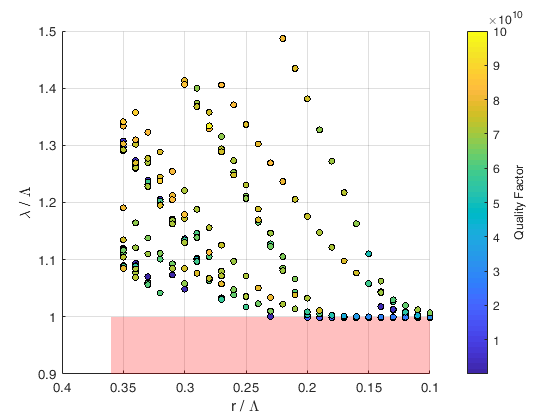

spheres_1_5


        zlabel('log_{10}(Q)');
        hold on;
        
    end
    %title(job, 'Interpreter', 'none');
    %axis([1 1.3 1200 1450 0 1e12]);
    view([-90 90]);
    cb = colorbar;
    ylabel(cb, 'Quality Factor');
    set(gca,'ColorScale','log');
    caxis([1e2 1e11]);
    
    %axis([0.9 1.6 0.1 0.25 0 1e12]);
    fill3([1 1 0.9 0.9], [0.36 0.1 0.1 0.36], [2 2 2 2], 'r', 'EdgeColor',...
        'none', 'FaceAlpha', 0.25);

    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_eig_sweep"), 'png');
end